data = readtable('data/data1/CHID46.csv');
disp(data);

    dpi    log_vRNA
    ___    ________

    13      4.0378 
    16      5.0338 
    20      5.9031 
    23      5.9649 
    27       5.532 
    30       4.891 
    36        4.44 
    38      4.1673 
    43      4.2634 



ans = 9

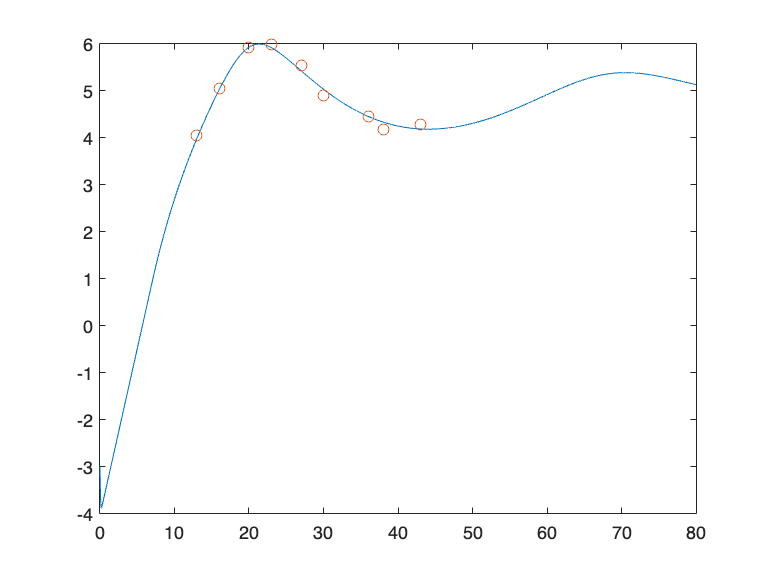

beta_0 = 4.09*(10^-7);
beta_ifty = 0.233*(10^-6);
k = 0.249;
dlt =  0.775;
p = 14.5*(10^3);
d = 0.030;

tau= 7;
c = 23;
f = @(t,x) [d*(10^4-x(1))-beta(t,tau,k,beta_0,beta_ifty)*x(1)*x(3);...
        beta(t,tau,k,beta_0,beta_ifty)*x(1)*x(3)-dlt*x(2);...
        p*x(2)-c*x(3) ];


h = 0.01;
interval = 0:h:80;    
[t,xa] = ode45(f,interval,[10^4 0 10^-3]);
pred = log10(xa(:,3));

plot(t,pred);


hold on;
scatter(data.dpi,data.log_vRNA);
hold off;

function out=beta(t,tau,k,beta_0,beta_ifty)
    if t <= tau
        out = beta_0;
    else
        out = beta_ifty+(beta_0-beta_ifty)*exp(-k*(t-tau));
    end
end
